clear; close all; clc;
addpath("../IAIA/Library/")

data_dir = "../IAIA/Dataset/CWRU_full_dataset/Raw_data/";
files = dir(fullfile(data_dir, "*.mat"));

fs = 12000;
num_segments = 15;

all_features = [];
all_labels   = [];
class_map = containers.Map;
label_id = 1;

for k = 1:length(files)

    fname = string(files(k).name);
    fpath = fullfile(files(k).folder, fname);

    fname = lower(fname);            
    tokens = split(fname, "_");      
    type = tokens(1);                

    if type == "normal"
        className = "normal";
    else
        className = type + "_" + tokens{2}; 
    end

    if ~isKey(class_map, className)
        class_map(className) = label_id;
        label_id = label_id + 1;
    end
    label = class_map(className);

    data = load(fpath);
    fields = fieldnames(data);
    idxDE = find(contains(fields, "_DE_time"), 1);
    idxFE = find(contains(fields, "_FE_time"), 1);

    if isempty(idxDE) || isempty(idxFE)
        continue;
    end

    DE = data.(fields{idxDE});
    FE = data.(fields{idxFE});
    RPM = 1797;
    idxRPM = find(contains(fields, "RPM"), 1);
    if ~isempty(idxRPM)
        RPM = data.(fields{idxRPM});
    end
    fr = RPM / 60;

    N = length(DE);
    seg_len = floor(N / num_segments);

    for seg = 1:num_segments
        idx1 = (seg-1)*seg_len + 1;
        idx2 = seg*seg_len;

        x_de = DE(idx1:idx2);
        x_fe = FE(idx1:idx2);

        feat_stat_DE = get_statistical_feature(x_de, fs);
        feat_stat_FE = get_statistical_feature(x_fe, fs);
        feat_env     = get_envelope_features(x_de, x_fe, fs, fr);
        feat_wav_DE  = get_wavelet_features(x_de);
        feat_wav_FE  = get_wavelet_features(x_fe);

        feat_vec = [feat_stat_DE, feat_stat_FE, feat_env, feat_wav_DE, feat_wav_FE];

        all_features = [all_features; feat_vec];
        all_labels   = [all_labels; label];
    end
end


X = zscore(all_features);
Y = categorical(all_labels);

cv = cvpartition(Y, 'KFold', 8);

eval_knn = @(X,Y,cv) (1 - kfoldLoss(crossval( ...
                fitcknn(X,Y,'NumNeighbors',1), 'CVPartition',cv))) * 100;

eval_svm = @(X,Y,cv) (1 - kfoldLoss(crossval( ...
                fitcecoc(X,Y,'Learners',templateSVM( ...
                'KernelFunction','rbf','Standardize',true,'KernelScale','auto')), ...
                'CVPartition',cv))) * 100;

eval_dtree = @(X,Y,cv) (1 - kfoldLoss(crossval( ...
                fitctree(X,Y), 'CVPartition',cv))) * 100;


n_stat = 26;
n_env  = 72;
n_wav  = 32;

X_stat = X(:, 1:n_stat);
X_env  = X(:, n_stat + (1:n_env));
X_wav  = X(:, n_stat + n_env + (1:n_wav));
X_full = X(:, 1:(n_stat+n_env+n_wav));

% evaluation
acc_stat_knn  = eval_knn(X_stat, Y, cv);
acc_stat_svm  = eval_svm(X_stat, Y, cv);
acc_stat_tree = eval_dtree(X_stat, Y, cv);

acc_env_knn  = eval_knn(X_env, Y, cv);
acc_env_svm  = eval_svm(X_env, Y, cv);
acc_env_tree = eval_dtree(X_env, Y, cv);

acc_wav_knn  = eval_knn(X_wav, Y, cv);
acc_wav_svm  = eval_svm(X_wav, Y, cv);
acc_wav_tree = eval_dtree(X_wav, Y, cv);

acc_full_knn  = eval_knn(X_full, Y, cv);
acc_full_svm  = eval_svm(X_full, Y, cv);
acc_full_tree = eval_dtree(X_full, Y, cv);


% accuracy
FeatureModel = {
    'Statistical';
    'Envelope';
    'Wavelet Packet';
    'Complete Pool'
};

KNN_1NN = [acc_stat_knn; acc_env_knn; acc_wav_knn; acc_full_knn];
SVM =     [acc_stat_svm; acc_env_svm; acc_wav_svm; acc_full_svm];
DTree =   [acc_stat_tree; acc_env_tree; acc_wav_tree; acc_full_tree];

ResultTable = table(FeatureModel, KNN_1NN, SVM, DTree)

ResultTable = 4×4 table
       FeatureModel       KNN_1NN     SVM      DTree 
    __________________    _______    ______    ______

    {'Statistical'   }       99         100    97.167
    {'Envelope'      }      100         100        95
    {'Wavelet Packet'}     99.5      99.667    99.667
    {'Complete Pool' }      100         100      98.5


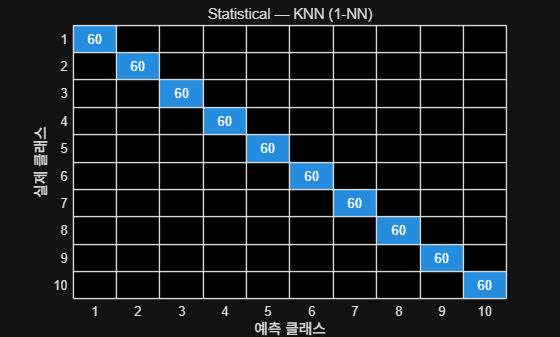

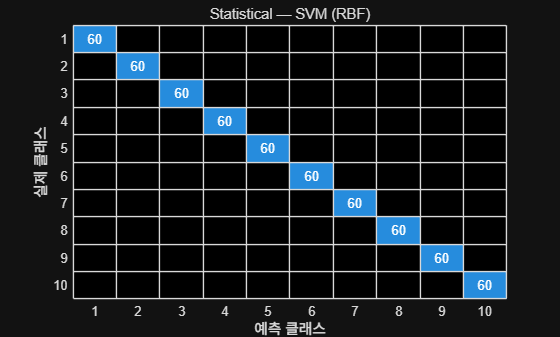

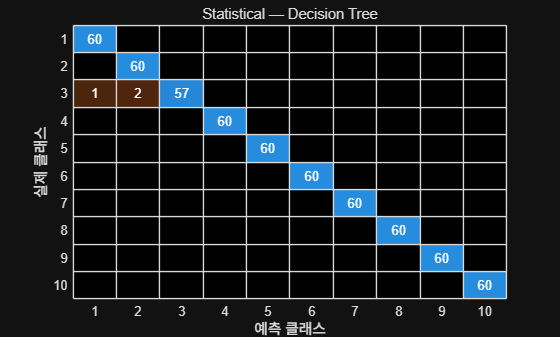

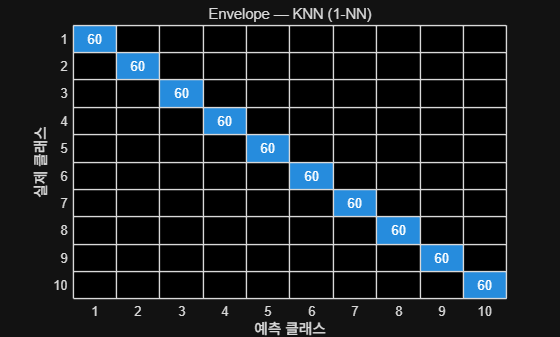

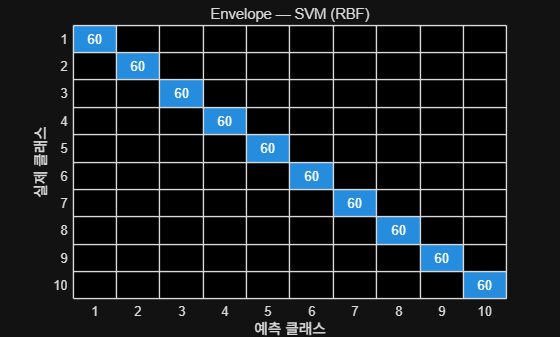

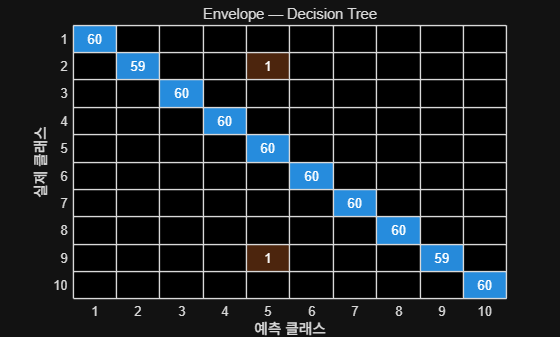

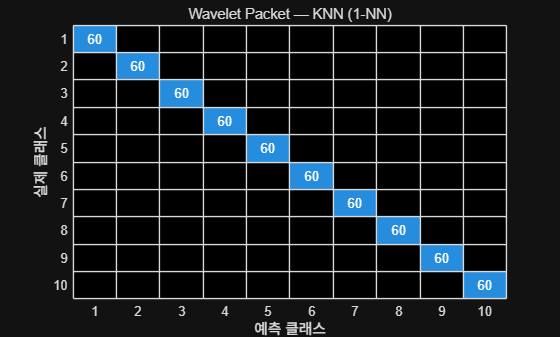

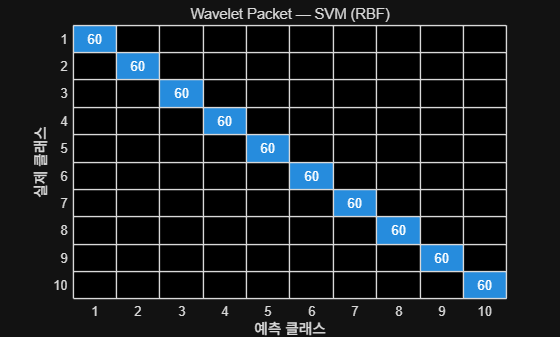

% confusion matrix

FeatureSets = { X_stat, X_env, X_wav, X_full };
FeatureNames = { "Statistical", "Envelope", "Wavelet Packet", "Complete Pool" };

for i = 1:4
    
    Xi = FeatureSets{i};
    fname = FeatureNames{i};

    % knn
    model_knn = fitcknn(Xi, Y, 'NumNeighbors', 1);
    Y_pred_knn = predict(model_knn, Xi);

    figure;
    confusionchart(Y, Y_pred_knn);
    title(fname + " — KNN (1-NN)");

    % svm
    model_svm = fitcecoc(Xi, Y, ...
        'Learners', templateSVM('KernelFunction','rbf','Standardize',true));
    Y_pred_svm = predict(model_svm, Xi);

    figure;
    confusionchart(Y, Y_pred_svm);
    title(fname + " — SVM (RBF)");


    % dtree
    model_tree = fitctree(Xi, Y);
    Y_pred_tree = predict(model_tree, Xi);

    figure;
    confusionchart(Y, Y_pred_tree);
    title(fname + " — Decision Tree");
end

% feature reduction and selection
opts = statset('display','iter');

fun_knn = @(train_x,train_y,test_x,test_y) ...
    sum(predict(fitcknn(train_x,train_y,'NumNeighbors',1), test_x) ~= test_y);

fun_svm = @(train_x,train_y,test_x,test_y) ...
    sum(predict(fitcecoc(train_x,train_y, ...
        'Learners',templateSVM('KernelFunction','rbf','Standardize',true)), test_x) ~= test_y);

fun_tree = @(train_x,train_y,test_x,test_y) ...
    sum(predict(fitctree(train_x,train_y), test_x) ~= test_y);

[fs_knn, history_knn] = sequentialfs(fun_knn, X_full, Y, 'cv', cv, 'options', opts);

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 1번 열 추가, 기준값 0.275
2단계, 12번 열 추가, 기준값 0.0216667
3단계, 2번 열 추가, 기준값 0
최종적으로 포함된 열: 1 2 12 


[fs_svm, ~] = sequentialfs(fun_svm, X_full, Y, 'cv', cv, 'options', opts);

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 1번 열 추가, 기준값 0.201667
2단계, 12번 열 추가, 기준값 0.0216667
3단계, 2번 열 추가, 기준값 0
최종적으로 포함된 열: 1 2 12 



[fs_tree, ~] = sequentialfs(fun_tree, X_full, Y, 'cv', cv, 'options', opts);

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 3번 열 추가, 기준값 0.261667
2단계, 11번 열 추가, 기준값 0.0483333
3단계, 109번 열 추가, 기준값 0.02
4단계, 26번 열 추가, 기준값 0.00666667
5단계, 10번 열 추가, 기준값 0.005
6단계, 106번 열 추가, 기준값 0.00333333
최종적으로 포함된 열: 3 10 11 26 106 109 



X_knn_sel  = X_full(:, fs_knn);
X_svm_sel  = X_full(:, fs_svm);
X_tree_sel = X_full(:, fs_tree);

acc_knn_sfs  = eval_knn(X_knn_sel,  Y, cv);
acc_svm_sfs  = eval_svm(X_svm_sel,  Y, cv);
acc_tree_sfs = eval_dtree(X_tree_sel, Y, cv);

% evalution
[coeff, score, latent, ~, explained] = pca(X_full);

cumvar = cumsum(explained);
pca_dim = find(cumvar >= 95, 1);   

fprintf("PCA selected %d components (95%% variance)\n", pca_dim);

PCA selected 18 components (95% variance)



Xpca = score(:, 1:pca_dim);

acc_pca_knn  = eval_knn(Xpca, Y, cv);
acc_pca_svm  = eval_svm(Xpca, Y, cv);
acc_pca_tree = eval_dtree(Xpca, Y, cv);

% accuracy
Method = {
    'PCA + KNN';
    'PCA + SVM';
    'PCA + DTree';
    'SFS + KNN';
    'SFS + SVM';
    'SFS + DTree'
};

Accuracy = [
    acc_pca_knn;
    acc_pca_svm;
    acc_pca_tree;
    acc_knn_sfs;
    acc_svm_sfs;
    acc_tree_sfs
];

SelectedDim = [
    pca_dim;
    pca_dim;
    pca_dim;
    sum(fs_knn);
    sum(fs_svm);
    sum(fs_tree)
];

Result_FS_PCA = table(Method, SelectedDim, Accuracy)

Result_FS_PCA = 6×3 table
        Method         SelectedDim    Accuracy
    _______________    ___________    ________

    {'PCA + KNN'  }        18             100 
    {'PCA + SVM'  }        18            99.5 
    {'PCA + DTree'}        18              98 
    {'SFS + KNN'  }         3             100 
    {'SFS + SVM'  }         3          99.833 
    {'SFS + DTree'}         6          99.333 


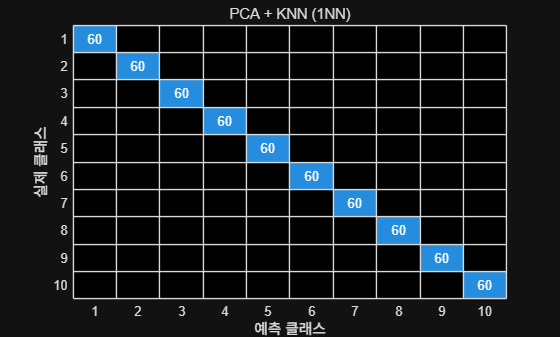

% Confustion Matrix

% PCA
% knn (PCA)
model_pca_knn = fitcknn(Xpca, Y, 'NumNeighbors', 1);
Y_pred_pca_knn = predict(model_pca_knn, Xpca);
figure;
confusionchart(Y, Y_pred_pca_knn);
title("PCA + KNN (1NN)");

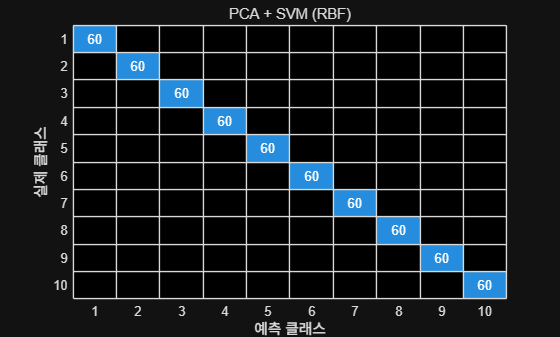


% svm (PCA)
model_pca_svm = fitcecoc(Xpca, Y, ...
        'Learners', templateSVM('KernelFunction','rbf','Standardize',true));
Y_pred_pca_svm = predict(model_pca_svm, Xpca);
figure;
confusionchart(Y, Y_pred_pca_svm);
title("PCA + SVM (RBF)");

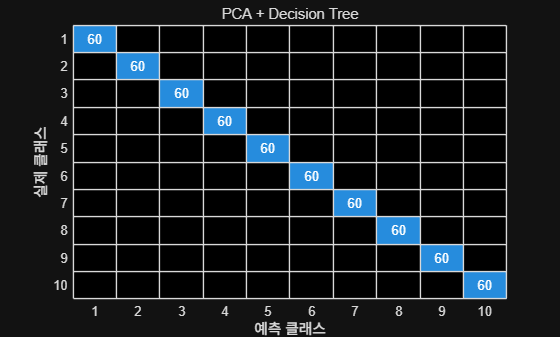


% dtree (PCA)
model_pca_tree = fitctree(Xpca, Y);
Y_pred_pca_tree = predict(model_pca_tree, Xpca);
figure;
confusionchart(Y, Y_pred_pca_tree);
title("PCA + Decision Tree");

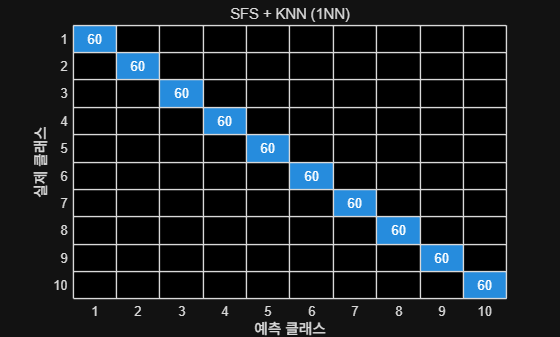



% SFS
% knn (SFS)
model_sfs_knn = fitcknn(X_knn_sel, Y, 'NumNeighbors', 1);
Y_pred_sfs_knn = predict(model_sfs_knn, X_knn_sel);
figure;
confusionchart(Y, Y_pred_sfs_knn);
title("SFS + KNN (1NN)");

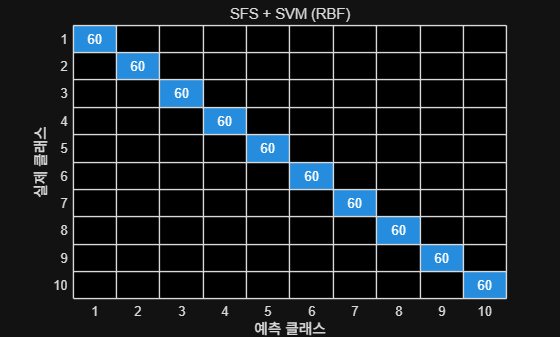


% svm (SFS)
model_sfs_svm = fitcecoc(X_svm_sel, Y, ...
        'Learners', templateSVM('KernelFunction','rbf','Standardize',true));
Y_pred_sfs_svm = predict(model_sfs_svm, X_svm_sel);
figure;
confusionchart(Y, Y_pred_sfs_svm);
title("SFS + SVM (RBF)");

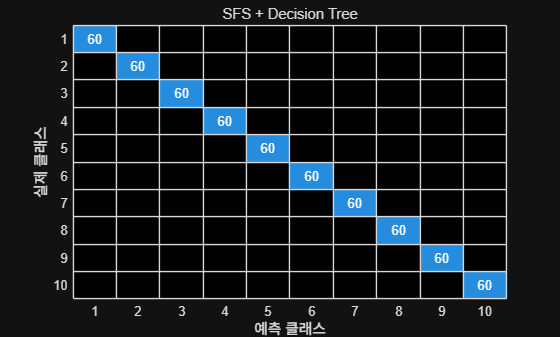


% dtree (SFS)
model_sfs_tree = fitctree(X_tree_sel, Y);
Y_pred_sfs_tree = predict(model_sfs_tree, X_tree_sel);
figure;
confusionchart(Y, Y_pred_sfs_tree);
title("SFS + Decision Tree");

function feat = get_statistical_feature(x, fs)

    T = timeFeatures_student(x);
    feat_time = [
        T.rms, T.sra, T.ppv, T.cf, T.if, ...
        T.mf, T.sf, T.sk, T.kt, T.kf
    ];
    
    L = length(x);
    P1 = getFFT_student(x, L);
    N = length(P1);
    f = (0:N-1) * (fs / (2*(N-1)));
    A = P1(:)';
    
    fc   = sum(f .* A) / sum(A);
    rmsf = sqrt(sum((f.^2).*A) / sum(A));
    rvf  = sqrt(sum((f - fc).^2 .* A) / sum(A));
    
    feat = [feat_time fc rmsf rvf];
end

function feat_env = get_envelope_features(DE, FE, fs, fr)
    fault_freqs = fr * [5.4152, 3.5848, 4.7135];
    DE_env = DE;
    FE_env = FE;
    N = length(DE_env);
    f = (0:N-1)*(fs/N);
    DE_spec = abs(fft(DE_env));
    FE_spec = abs(fft(FE_env));
    f_axis = (0:N-1)*(fs/N);
    BW = 0.01;
    extract = @(spec,f0) arrayfun(@(h) rms(spec(f>=f0*h*(1-BW) & f<=f0*h*(1+BW))), 1:6);
    feat_env = [];
    
    for fi = 1:3
        feat_env = [feat_env extract(DE_spec, fault_freqs(fi))];
    end
    
    for fi = 1:3
        feat_env = [feat_env extract(FE_spec, fault_freqs(fi))];
    end
    
    for fi = 1:3
        feat_env = [feat_env extract(DE_spec, fault_freqs(fi))];   % cross-detection
    end
    
    for fi = 1:3
        feat_env = [feat_env extract(FE_spec, fault_freqs(fi))];   % cross-detection
    end

end

function feat_wav = get_wavelet_features(x)
    x = x(:)';
    wp = wpdec(x, 4, 'db4');
    feat_wav = zeros(1,16);
    total_energy = 0;
    for n=0:15
        c = wpcoef(wp,[4 n]);
        E = sum(c.^2);
        feat_wav(n+1)=E;
        total_energy=total_energy+E;
    end
    if total_energy == 0
        feat_wav = zeros(1,16);
    else
        feat_wav = feat_wav / total_energy;
    end

end
